# Physical Modelling Sound Synthesis

*Intro Lecture - 24 Feb 2025*

## Numerical Integration of the Simple Harmonic Oscillator

Vibration modelling is central to physical modelling sound synthesis. A balance between stability, efficiency and accuracy characterises the schemes employed in solving the models, either PDEs or ODEs.

Regarding accuracy: order-accuracy is not the only thing that matters! Consider a classic integrator of the Runge-Kutta type (RK4). 

*Set the oscillator properties and the sample rate. As a first example, consider f0 = 300 Hz. *

%---- Integrator of the oscillator equation using RK4
%     Michele Ducceschi
%     24 Feb 2025
%-----------------------------------------------------

%clear all
%close all
clc

%-- global parameters

f0      = 300 ;      %-- osc freq [Hz]
T       = 3 ;         %-- sim time [s]
fs      = 48e3 ;      %-- sample rate [Hz]

%-- initial conditions
u0      = 1 ;        %-- initial disp
v0      = 0 ;        %-- initial vel

*Initialise the scheme and compute exact solution for comparison*

om0     = 2*pi*f0 ;
k       = 1/fs ;
Ts      = floor(T*fs) ;
tv      = (0:Ts-1)*k ;
exsol   = u0*cos(om0*tv) + v0/om0*sin(om0*tv) ; %-- exact solution

%-- scheme init
numsol    = zeros(Ts,1) ;
numsol(1) = exsol(1) ;
numsol(2) = exsol(2) ;

*Main loop: four-stage RK4 scheme*


for n = 3 : Ts

    r1  = [v0;-om0^2*u0] ;
    yt  = [u0;v0] + 0.5*k*r1 ;
    r2  = [yt(2); -om0^2*yt(1)] ;
    yt  = [u0;v0] + 0.5*k*r2 ;
    r3  = [yt(2); -om0^2*yt(1)] ;
    yt  = [u0;v0] + k*r3 ;
    r4  = [yt(2); -om0^2*yt(1)] ;


    upd = [u0;v0] + (1/6) * k * (r1+2*r2+2*r3+r4) ;


    u0 = upd(1) ; v0 = upd(2) ;
    numsol(n) = u0 ; %-- save solution to array

end


*Plot solutions and play sound*

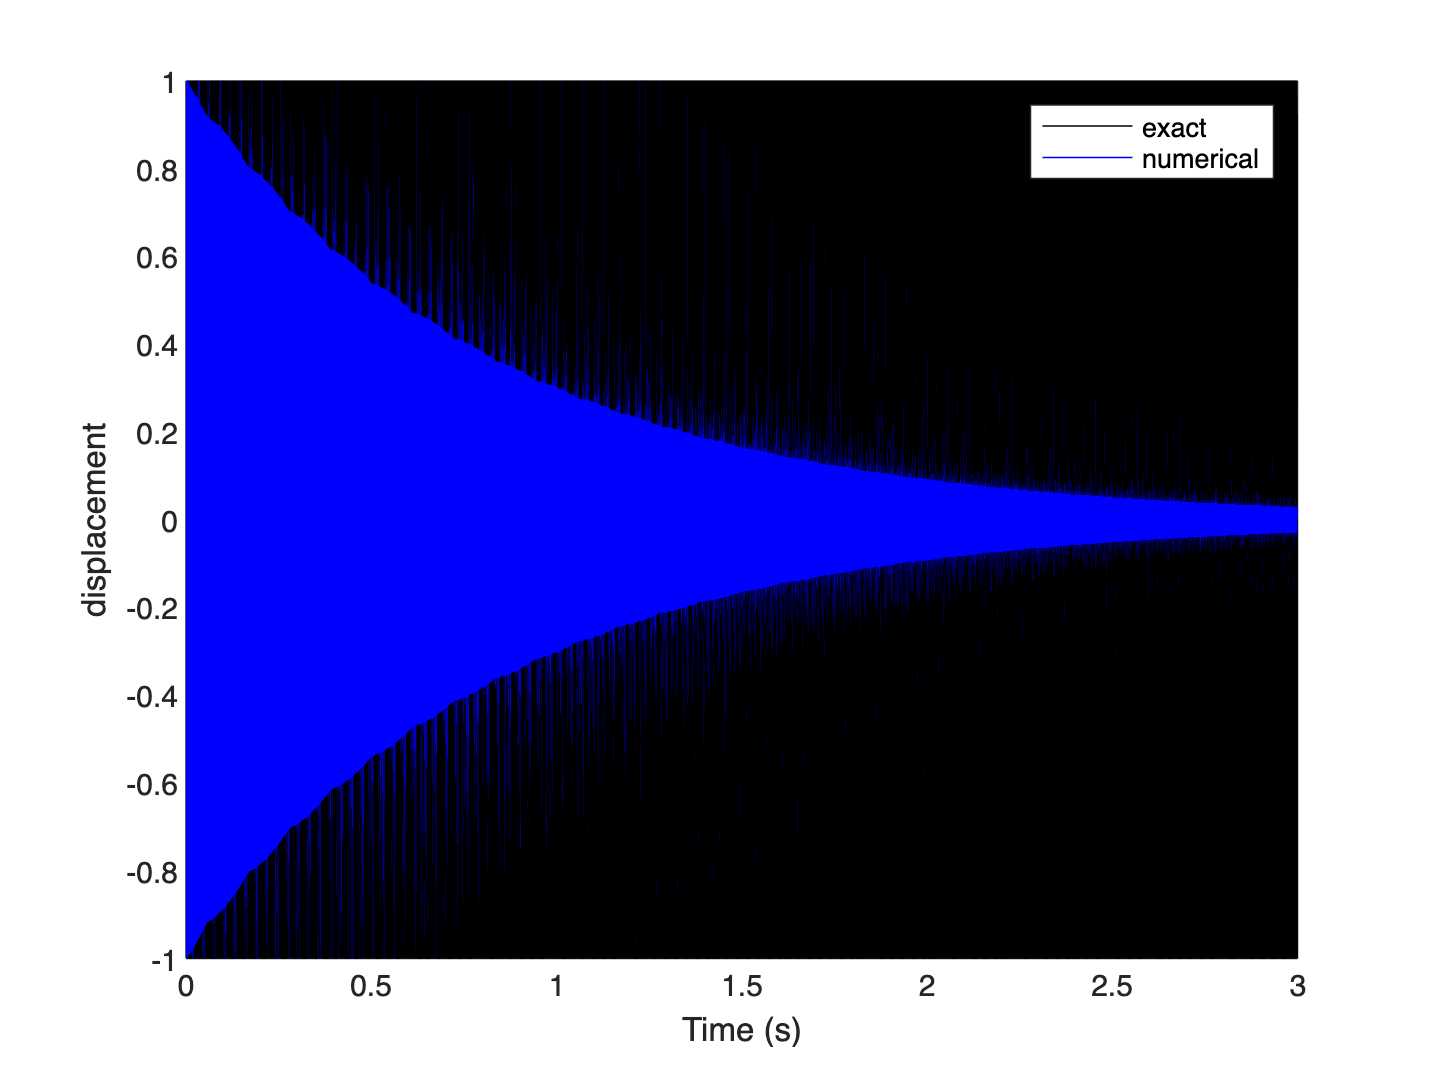

figure ;
plot(tv,exsol,'k') ; hold on ;
plot(tv,numsol,'b') ;
legend('exact','numerical');
xlabel('Time (s)');
ylabel('displacement');

%xlim([0.075,0.09])



%soundsc(exsol,fs); pause(T+0.1)
%soundsc(numsol,fs);

- The RK method looks good for low f0 (eg < 1000) for typical audio sample rates! (fs = 48e3)

- What happens when f0 is larger though? Say, f0 = 3000?

The explicit Runge-Kutta introduces a kind of artificial damping, which is obviously unwanted when the purpose is musical (many time steps, sustained tones, etc). 

Numerical order-accuracy does not scale with perceptual accuracy

Let's consider a different scheme, the "leapfrog" (or Störmer-Verlet) algorithm.

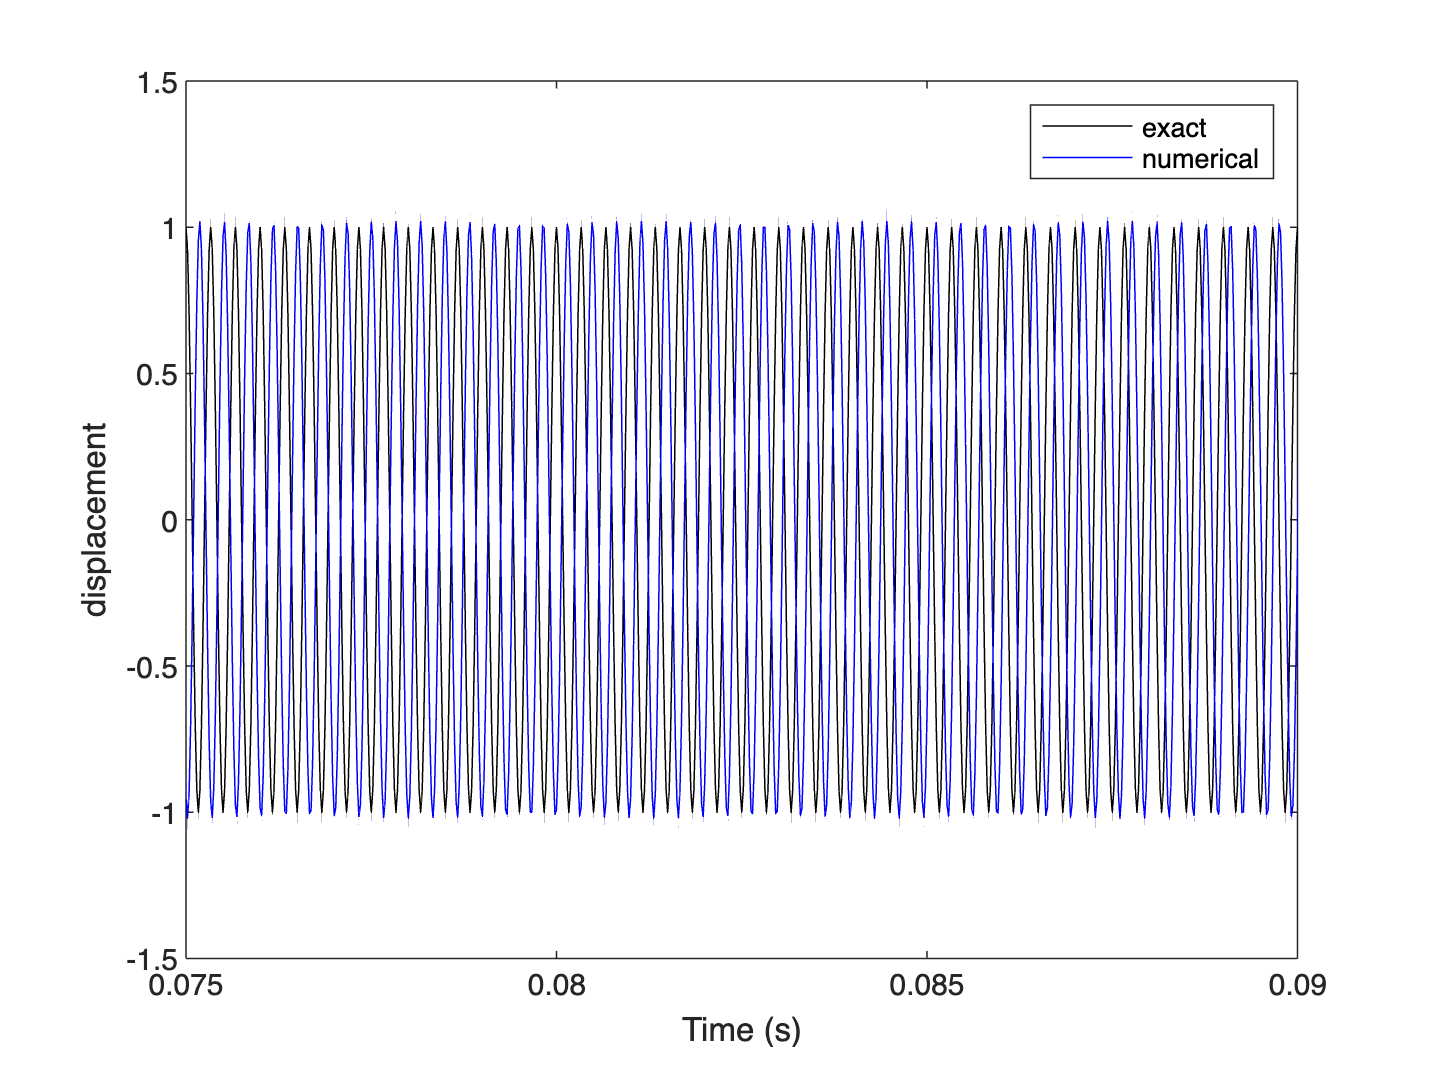

%---- Integrator of the oscillator equation using SV (leapfrog)
%     Michele Ducceschi
%     24 Feb 2025
%-----------------------------------------------------

% clear all
% close all
clc

%-- global parameters

f0      = 3000 ;      %-- osc freq [Hz]
T       = 3 ;         %-- sim time [s]
fs      = 48e3 ;      %-- sample rate [Hz]

%-- initial conditions
u0      = 1 ;        %-- initial disp
v0      = 0 ;        %-- initial vel


om0     = 2*pi*f0 ;
k       = 1/fs ;
Ts      = floor(T*fs) ;
tv      = (0:Ts-1)*k ;
exsol   = u0*cos(om0*tv) + v0/om0*sin(om0*tv) ; %-- exact solution

%-- scheme init
numsol    = zeros(Ts,1) ;
numsol(1) = exsol(1) ;
numsol(2) = exsol(2) ;


% Time integration using the Leapfrog method
for n = 3:Ts

    % Full step velocity update
    vp = v0 + k * (-om0^2 * u0);
    % Full step position update
    up = u0 + k * vp;

    %-- save current displacement
    numsol(n) = up ;

    % Update state
    u0 = up;
    v0 = vp;
end

% Plot the results
figure;
plot(tv,exsol,'k') ; hold on ;
plot(tv,numsol,'b') ;
legend('exact','numerical');
xlabel('Time (s)');
ylabel('displacement');
xlim([0.075,0.09])

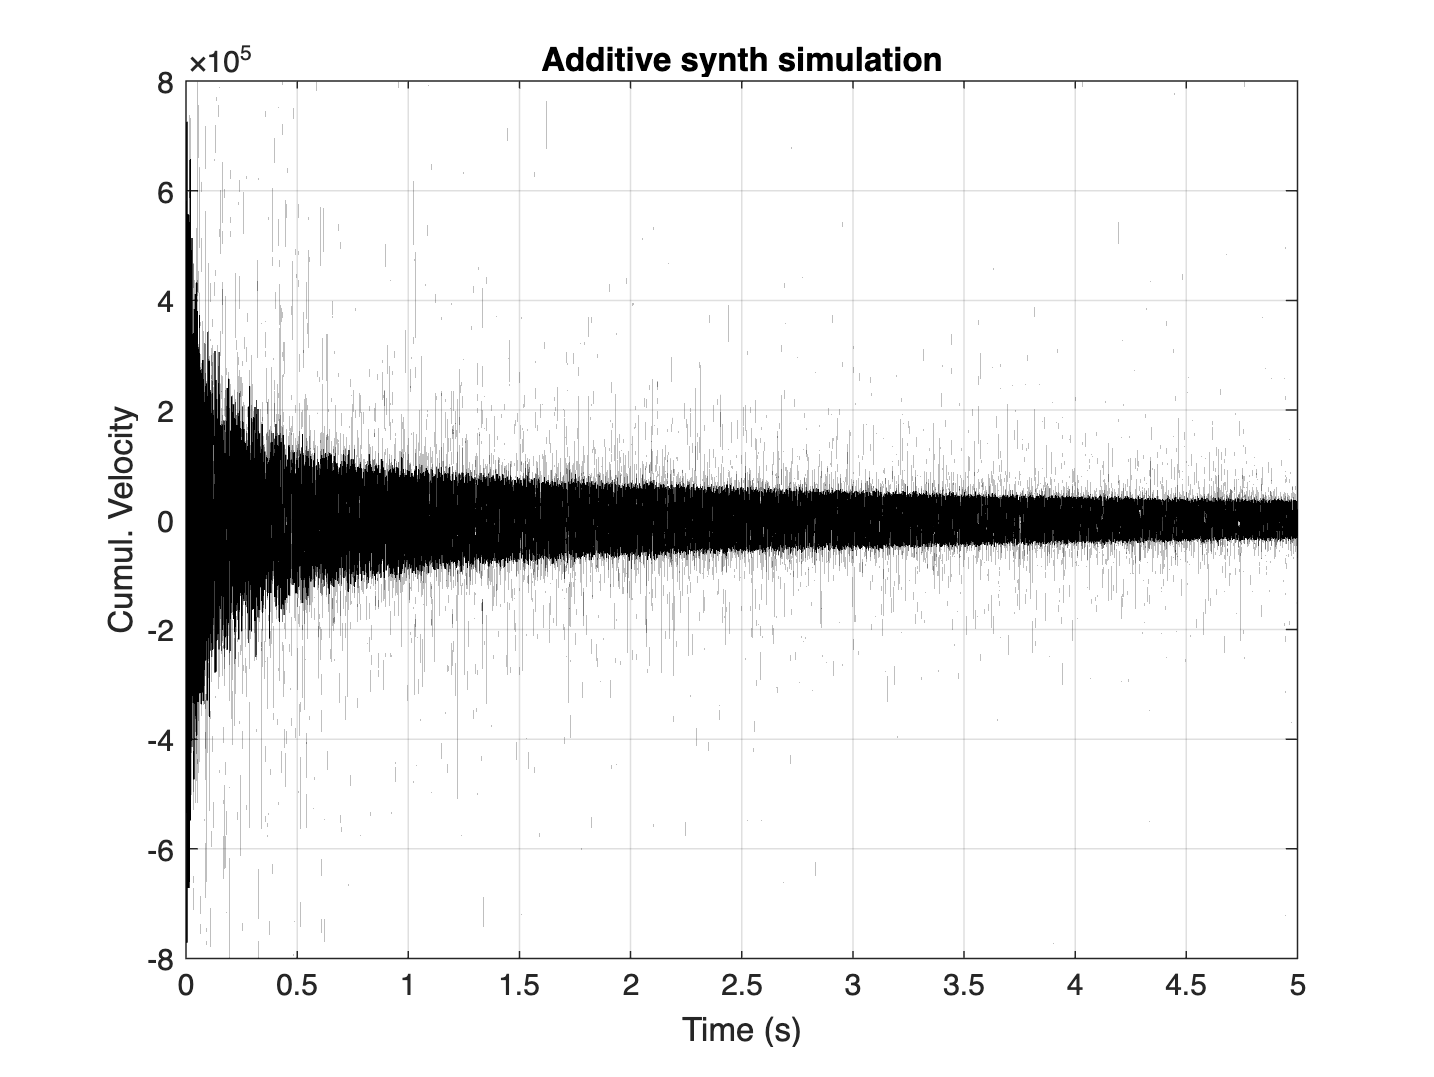

%---- Example of additive synthesiser using SV
%     Michele Ducceschi
%     24 Feb 2025
%-----------------------------------------------------


% clear all
% close all
clc

%-- global parameters
N  = 500 ;    %-- Number of oscillators
fs = 48e3 ;   %-- Sample rate [Hz]
T  = 5 ;      %-- Total simulation time
%-----------------------------------------------------

%-- init
% Simulation parameters
k = 1/fs;  % Time step

Ts = round(T / k);

% Randomly initialize system parameters
om0 = 2 * pi * (0.5 + 10000*rand(1, N));   % Random natural frequencies (0.5 Hz to 1.5 Hz)
gamma = 1000*(0.05 * rand(1, N));                  % Random damping coefficients (small damping)
u0 = rand(1, N) - 0.5;                       % Initial positions
v0 = rand(1, N) - 0.5;                       % Initial velocities

% Allocate arrays for storing results
numdisp = zeros(Ts, N);
numvel = zeros(Ts, N);
tv = (0:Ts-1) * k;

% First half-step for velocity (Leapfrog scheme)
v0 = v0 - 0.5 * k * (-om0.^2 .* u0 - 2 * gamma .* v0);
%-----------------------------------------------------


%-- main loop
for n = 1:Ts
    % Store the current state
    numdisp(n, :) = u0;
    numvel(n, :) = v0;

    % Full step for position
    up = u0 + k * v0;

    % Full step for velocity
    vp = v0 - k * (om0.^2 .* up + 2 * gamma .* v0);

    % Update state
    u0 = up;
    v0 = vp;
end

vel_sum = sum(numvel,2) ;


% Plot the results
figure ;
plot(tv, vel_sum,'k');
xlabel('Time (s)');
ylabel('Cumul. Velocity');
title('Additive synth simulation');
grid on;


soundsc(vel_sum,fs)